# Project2 : Motion detection via communication signals

涂峻绫(12213010), 欧阳莹轩(12212961), 肖星辰(12212904), 欧阳安男(12211831)

## Introduction

## Results and Analysis

### Task 1

- For the reference signal and the surveillance signal, draw their time domain waveforms and their frequency domain waveforms.

Initialize and load audio to $ref$ and $sur$.

clear;clc;
load('proj2/data_1.mat');
t = 1/f_s : 1/f_s : 0.5;
t_ms = t*1000;
ref = seq_ref;
sur = seq_sur;

Do Digital Down Convert (DDC).

f_ddc = -3*1e6;
ref_ddc = ref .* exp(-1i * 2*pi * f_ddc * t);
sur_ddc = sur .* exp(-1i * 2*pi * f_ddc * t);

Do Low Pass Filter (LPF).

f_cutoff = 9*1e6;
[b,a] = butter(26, f_cutoff/(f_s/2));
ref_lpf = filter(b, a, ref_ddc);
sur_lpf = filter(b, a, sur_ddc);

Calculate spectrum.

freq_mhz = 2110-2123+2e-6 : 2e-6 : 2135-2123;
ref_freq = abs(fftshift(fft(ref)));
sur_freq = abs(fftshift(fft(sur)));
ref_ddc_freq = abs(fftshift(fft(ref_ddc)));
sur_ddc_freq = abs(fftshift(fft(sur_ddc)));
ref_lpf_freq = abs(fftshift(fft(ref_lpf)));
sur_lpf_freq = abs(fftshift(fft(sur_lpf)));

Calculate dB.

ref_freq_db = 20 * log10(ref_freq / max(ref_freq));
sur_freq_db = 20 * log10(sur_freq / max(sur_freq));
ref_ddc_freq_db = 20 * log10(ref_ddc_freq / max(ref_ddc_freq));
sur_ddc_freq_db = 20 * log10(sur_ddc_freq / max(sur_ddc_freq));
ref_lpf_freq_db = 20 * log10(ref_lpf_freq / max(ref_lpf_freq));
sur_lpf_freq_db = 20 * log10(sur_lpf_freq / max(sur_lpf_freq));

Plot.

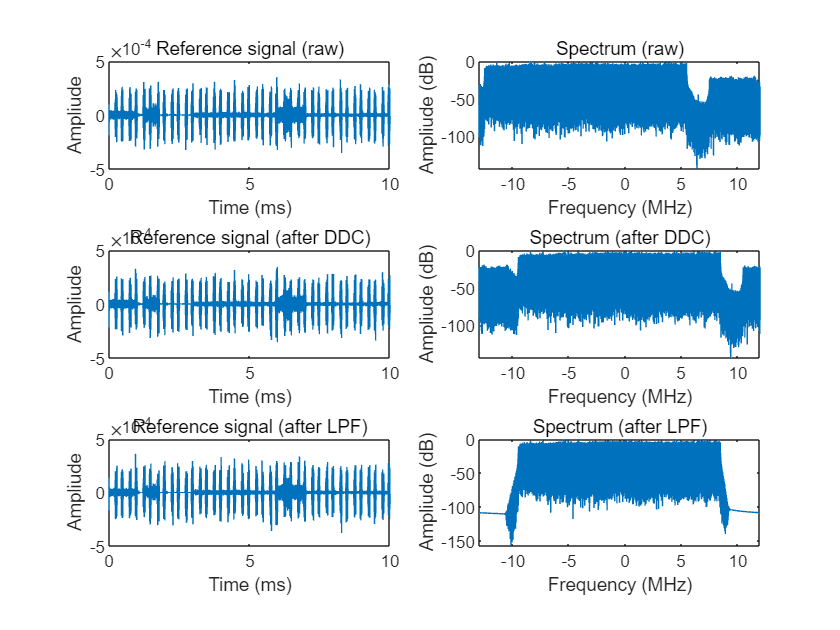

figure;
task1plot(1, 'Reference signal (raw)', t_ms, real(ref), true);
task1plot(3, 'Reference signal (after DDC)', t_ms, real(ref_ddc), true);
task1plot(5, 'Reference signal (after LPF)', t_ms, real(ref_lpf), true);
task1plot(2, 'Spectrum (raw)', freq_mhz, ref_freq_db, false);
task1plot(4, 'Spectrum (after DDC)', freq_mhz, ref_ddc_freq_db, false);
task1plot(6, 'Spectrum (after LPF)', freq_mhz, ref_lpf_freq_db, false);

#### Description

### Task 2

- Plot the Range Doppler spectrum of the signal located at 0-0.5s, 2-2.5s, 5-5.5s and 7-7.5s.

#### Description

### Task 3

- Plot the T ime Doppler spectrum with coherent integration time (CIT) equal to 0.5s. Time range is 0-9.5s.

#### Description

### Functions

The function to plot in task1.

function task1plot(plot_idx, title_name, x, y, is_t_domain)
subplot(3, 2, plot_idx);
plot(x, y);
title(title_name);
if is_t_domain
    xlabel('Time (ms)');
    ylabel('Ampliude');
    xlim([0 10]);
else
    xlabel('Frequency (MHz)');
    ylabel('Ampliude (dB)');
end
end

### Summary

## Expeience

........................